# Optimal Missile Guidance

In this exercise you will implement a simple model of missile dynamics and guidance, use an ODE solver to estimate the missile trajectory and then implement an optimization solver to find the optimal guiance parameters that balance time-to-target and energy useage (control effort).  

- Create a model of the open-loop missile dynamics and implement a numerical solution to the model to predict the trajectory.

- Incorporate Augmented Proportional Navigtion (APN), a common guidance technique to guide the simulated missile to a fixed target.

- Explore the sensitivity of the performance to the APN parameters.

- Formulate a cost function to balance trajectory time and effort.

- Use optimization to find the "best" guidance parameters to minimize time and effort.

The steps below are meant to be incremental, putting the pieces together one at a time to formulate the optimization problem.

## Missile Model

Create a model of the open-loop missile dynamics and implement a numerical solution to the model to predict the trajectory.

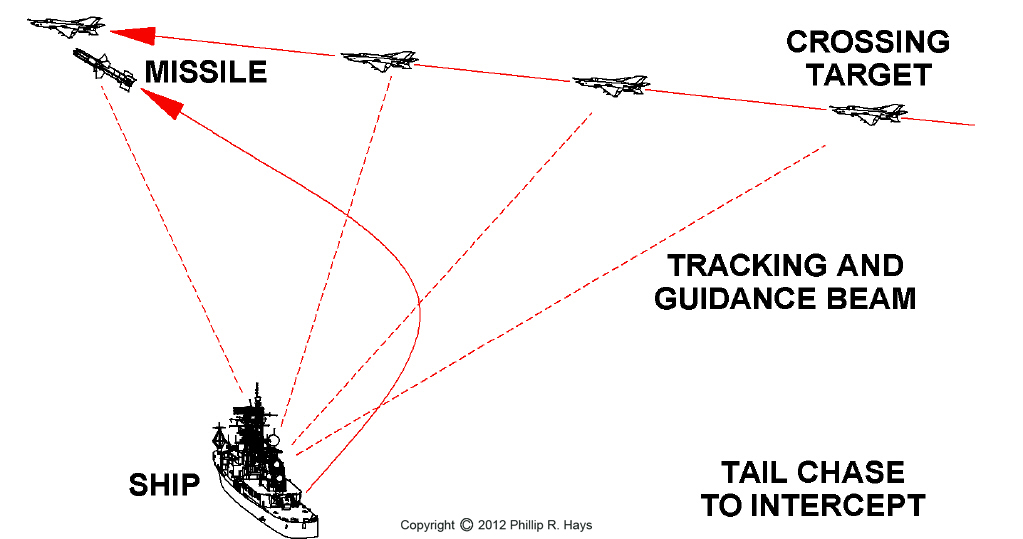

Consider a simple kinematic model of a missile in the horizontal plane.

The state of the system is defined as


$$\mathbf{x}(t)=\left\{ \matrix{ x(t) \cr y(t)\cr \dot{x}(t) = v_x(t) \cr \dot{y}(t) = v_y(t) }\right\}
$$


where 

- $x(t)$ is the position east

- $y(t)$ is the position north

- $v_x(t)$ is thevelocity component in the east direction

- $v_y(t)$ is the velocity component in the north direction.

This rate function describes a simple kinematic model in 2D with zero acceleration.

function dxxdt = missile(t, xx)
    % First, unpack the state vector 
    x = xx(1);   % m
    y = xx(2);   % m
    vx = xx(3);  % m/s
    vy = xx(4);  % m/s

    % Next, write your equations of motion
    dxdt = vx;      % m/s
    dydt = vy;      % m/s
    dvxdt = 0;      % m/s^2
    dvydt = 0;  % m/s^2
    
    % Finally, reassemble the output vector dX/dt
    dxxdt= [dxdt;dydt;dvxdt;dvydt];
end

We'll consider a reasonable initial velocity based on the [RIM-174 Standard ERAM](https://en.wikipedia.org/wiki/RIM-174_Standard_ERAM)

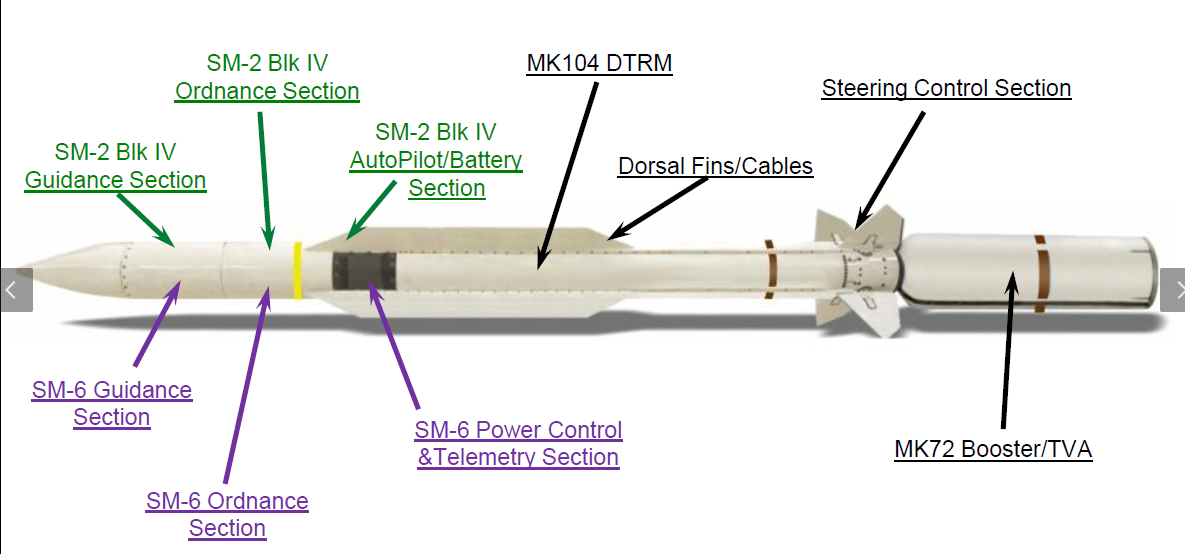

For this exercise we'll consider this constant set of initial conditions, including a constant firing angle of north-east (45 degrees).

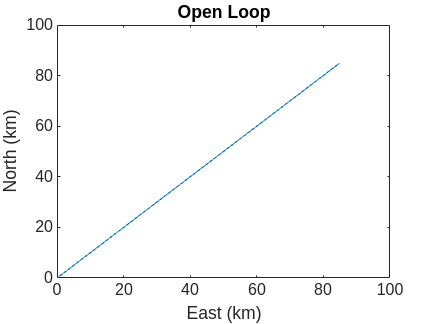

% Initial conditions
% RIM-174 ERAM Standard SM-6
v0 = 1200; % m/s
theta = pi/4;  % rad

x0 = 0;
y0 = 0;
vx0 = v0*cos(theta);
vy0 = v0*sin(theta);
xx0 = [x0; y0; vx0; vy0];


Use `ode45` to simulate the missile dynamics for 100 seconds with the initial conditions above.

% Time span
tspan = [0, 100];

% Solver

[tt, xx] = ode45(@missile, tspan, xx0);

From the dynamics, we would expect that the missile would travel a straight trajectory to the northeast.  Furthermore, based on the velocity and the time span we could estimate how far it would travel.  Plot the trajectory (x vs y states) of the missile to verify that the results match our prediction.   Plot the distances in units of km to make it a bit easier to view.

figure;
plot(xx(:,1)/1000, xx(:,2)/1000)
title('Open Loop')
xlabel('East (km)')
ylabel('North (km)')

## Implement Augmented Proportional Navigation (APN) and Fixed Target

Incorporate Augmented Proportional Navigtion (APN), a common guidance technique to guide the simulated missile to a fixed target.

Now that we have the missile dynamics working we can add the guidance law and a fixed target location.   The [APN guidlance law](https://en.wikipedia.org/wiki/Proportional_navigation) is expressed as


$$a_n = N \dot{\lambda} V + B$$


where

- $a_n$ is the normal acceleration

- $N$is the proportioal gain design parameter

- $\dot{\lambda}$ is the rate of change of the line of sight from the missile to the target

- $V $is the closing velocity.

To implement this guidance law we need to be able to formulate it in terms of the state of the system for a target at the fixed position $x_{tgt}$ , $y_{tgt}$.


$$ \lambda = \arctan{\frac{y_{tgt}-y}{x_{tgt}-x}}$$



$$\dot{\lambda} = \frac{(y_{tgt}-y)v_y - (y_{tgt} -y) v_x}{R^2}$$


where $R$ is the distance from the missile to the target position.  The resulting acceleration command has $x$ and $y$ components:


$$a_x = \ddot{x} = \dot{v}_x = a_n * cos(\lambda) 
$$



$$a_y = \ddot{y} = \dot{v}_y = a_n * sin(\lambda) 
$$


Based on the `missile` rate function above, create a new `missile_apn` rate function and include the following

- A fixed target tlocation of $x_{tgt}=200,000$ m and $y_{tgt} = 20,000$ m.

- Fixed APN design parameters $N = 1$ and $B = 100$.

- Calculate the APN guidance accelerations $a_x$ and $a_y$ at the current state.

- Apply the accelerations by setting $\dot{v}_x-a_x$ and $\dot{v}_y-a_y$ in the output of the rate function.

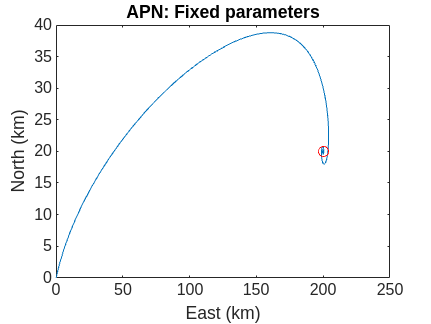

function dxxdt = missile_apn(t, xx)
    % First, unpack the state vector 
    x = xx(1);   % m
    y = xx(2);   % m
    vx = xx(3);  % m/s

    vy = xx(4);  % m/s

    % Target location - fixed
    x_tgt = 200000;
    y_tgt = 20000;
   
    % Fixed APN parameters.
    N = 1;
    B = 100;

    % Guidance law: APN
    R = sqrt((y_tgt-y)^2 + (x_tgt-x)^2);
    LOS = atan2(y_tgt-y, x_tgt-x);
    LOS_rate = ((x_tgt-x)*vy - (y_tgt-y)*vx) / (R^2);
    v = sqrt(vx^2 + vy^2);
    a = N* v*LOS_rate + B;
    
    % Next, write your equations of motion
    dxdt = vx;      % m/s
    dydt = vy;      % m/s
    dvxdt = a*cos(LOS);      % m/s^2
    dvydt = a*sin(LOS);  % m/s^2
    
    % Finally, reassemble the output vector dX/dt
    dxxdt= [dxdt;dydt;dvxdt;dvydt];
end

Simulate the trajectory of the missile by solving the ODE.

tspan = [0, 100];
xx0 = [x0; y0; vx0; vy0];
[tt, xx] = ode45(@missile_apn, tspan, xx0);

dxxdt =   848.5281
  848.5281
  104.0179
   10.4018


When you run the solver, you will likely get a warning similar to the following...

You can avoid this by adding an [event function](https://www.mathworks.com/help/matlab/math/ode-event-location.html), as demonstrated in the PMM baseball example, but the warning actually stops the simulation, when the trajectory is close to the target, so we can treat this bug as a feature for now.

You may find that this warning message clutters your output.  You can [suppress the warning](https://www.mathworks.com/help/matlab/matlab_prog/suppress-warnings.html) like this...

warning('off', 'MATLAB:ode45:IntegrationTolNotMet');

Plot the resulting trajectory as before.  Annotate the plot with a red marker (`ro`) at the fixed target location so that you can easily see if the missile intercepted the target.

figure;
clf;
plot(xx(:,1)/1000, xx(:,2)/1000)
hold on;
plot(200, 20, 'ro')

dxxdt =   848.5281
  848.5281
  104.0179
   10.4018


title( sprintf("APN: Fixed parameters"))
xlabel('East (km)')
ylabel('North (km)')

dxxdt =   848.5281
  848.5281
    9.0283
    0.9028


## Parameterize the problem with an anonymous function.

In the setup above the guidance parameters, N and B, are fixed within the rate function.  We want to be able to vary those from outside of the rate function so that we can access them without changing the rate function.  This is a key step in order to give our optimization solver the access it needs to vary the problem parameters.

Re-write the rate function `missile_apn`, call the new one `missile_apn_parameterized`, so that it now takes one additional input argument, `params`, which is a two-element vector containing values for N and B.  The function is essentialy the same as above, just with adding an additional input arguement and then unpacking the `params` vector into scalars for N and B.

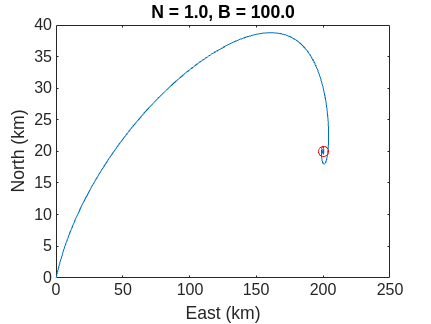

function dxxdt = missile_apn_parameterized(t, xx, params)
    % First, unpack the state vector 
    x = xx(1);   % m
    y = xx(2);   % m
    vx = xx(3);  % m/s
    vy = xx(4);  % m/s

    % Target location - fixed
    x_tgt = 200000;
    y_tgt = 20000;

    
    % Guidance parameters
    N = params(1);
    B = params(2);

    % Guidance law: APN
    R = sqrt((y_tgt-y)^2 + (x_tgt-x)^2);
    LOS = atan2(y_tgt-y, x_tgt-x);
    LOS_rate = ((x_tgt-x)*vy - (y_tgt-y)*vx) / (R^2);
    v = sqrt(vx^2 + vy^2);
    a = N* v*LOS_rate + B;
    
    % Next, write your equations of motion
    dxdt = vx;      % m/s
    dydt = vy;      % m/s

t_cost = 49.1071

    dvxdt = a*cos(LOS);      % m/s^2
    dvydt = a*sin(LOS);  % m/s^2

Time cost: 4.910705e+01, Effort cost: 1.497854e+00, Total cost: 5.060491e+01 


    
    % Finally, reassemble the output vector dX/dt
    dxxdt= [dxdt;dydt;dvxdt;dvydt];
end

A first test is to call the function at a fixed point in time:

N = 1;
B = 100;
dxxdt = missile_apn_parameterized(0, xx0, [N, B])

cost = 104.7628

### Anonymous function handle wrapper

Because the interface for the ODE sovler requires that the rate function only has arguments of `(t,y)`, we need to "wrap" the `missile_apn_parameterized` with an anonymous function. Write an anonymous function that creates a function handle named `odefun` with input arguments `(t,y)y`).  The anonymous function will execute the parameterized rate function at specified values of N and B.

N = 1;
B = 100;

p_opt =    11.9252   31.6950


params = [N, B];
odefun = @(t,y) missile_apn_parameterized(t, y, params);

Test our new anonymous function handle and verify that it provides the same output as the above call to the `missile_apn_parameterized` function:

dxxdt = odefun(0, xx0)

Now re-create the anonymous function handle, call it `new_odefun`,  with N = 2 and B = 0 and verify that the results have changed.

new_odefun = @(t,y) missile_apn_parameterized(t, y, [2 0]);
dxxdt = new_odefun(0, xx0)

### Use ODE sover with anonymous function.

And then pass this anonymous function handle, `ode45` to the solver.

[tt, xx] = ode45(odefun, tspan, xx0);

Verify that you get the same trajectory as before (make sure you have defined N and B equivalently) by plotting the trajectory and the target.

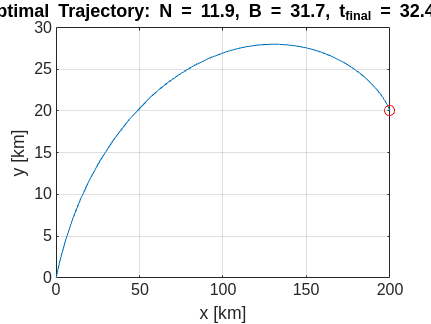

figure;
clf;
plot(xx(:,1)/1000, xx(:,2)/1000)
hold on;
plot(200, 20, 'ro')
title(sprintf("N = %.1f, B = %.1f", params(1), params(2)))
xlabel('East (km)')
ylabel('North (km)')

## Guidance Behavior

Now that we have a parameterized rate function, with the design parameters exposed, we can explore the sensitivity of the performance to the APN parameters.  

Change the parameters of the guidance law, $N$ and $B$ , in the section above and re-run the section create a new `odefun` rate function handle to pas to the ODE solver.  The plot should allow you to see how the trajectory changes.   A part of the our objective is to minimize the time it takes to intercept the target.   The time is the last element in the time vector returned in the solution.

Record your observations by adding text to this text block of the live script.

What happens to the trajectory and the intercept time when you...

- Make N "small"?

- Make N "large"?

- Remove B by setting it to zero?

- Make B "large"?

- How would you set N and B to achieve a minimum time intercept?

## Formulate a cost/objective function

Formulate a cost function to balance trajectory time and effort.


$$\text{cost} =  \underbrace{t_f}_\text{time cost} + \underbrace{ Ke \cdot\frac{\sqrt{\sum_{i=1}^M v_{x_i}^2+v_{y_i}^2}}M}_{\text{effort cost}}$$


- Time cost: the intercept time. The final element in the time vector returned by `ode45`

- Effort cost: the RMS of the velocity states from the solution.  Because we have the vectors $v_x$ and $v_y$ from the ODE solution, we can use element-wise artimetic and the `sum` function to calculate this part of the cost.

- The constant $K_e = 1e8$ is a normalizing constant to balance the weight on time and effort.

Write a few lines to calculate the time cost, the effort cost and the total cost for the current solution.  This should only take 3 lines of code.

t_cost = tt(end)
e_cost = (1/1e8)*sqrt(sum(xx(:,3).^2+xx(:,4).^2))/length(xx(:,3));
fprintf("Time cost: %e, Effort cost: %e, Total cost: %e \n",t_cost, e_cost, t_cost+e_cost);

## Use optimization to find the "best" guidance parameters to minimize time and effort.

Now we can assemble a single function that takes in our two design parameters, the N and B guidance parameters, and returns the total cost.  All the pieces are above, we need to copy them into this one function that we will pass to the optimization algorithm.

function cost = cost_function(params)
    % Initial conditions
    v0 = 1200; % m/s
    theta = pi/4;  % rad
    x0 = 0;
    y0 = 0;
    vx0 = v0*cos(theta);
    vy0 = v0*sin(theta);
    xx0 = [x0; y0; vx0; vy0];
    
    % Time span
    tspan = [0, 1000];
    
    % Define anonymous function to point to the `missile_apn_parameterized`
    % rate function, passing in the values for N and B.
    odefun = @(t,y) missile_apn_parameterized(t, y, params);

    % Solve the ODE
    [tt, xx] = ode45(odefun, tspan, xx0);

    % Calculate the total cost from the ODE solution.
    t_cost = tt(end);
    e_cost = (1/1e8)*sqrt(sum(xx(:,3).^2+xx(:,4).^2))/length(xx(:,3));
    cost = t_cost + e_cost;
end

Verify that this cost function works correcty be testing it with our known solution.  For our initial values of N and B, verify that the function returns the same cost that we calculated previously.

N = 1;
B = 10;
cost = cost_function([N, B])

## Optimize

The hard work is (hopefully) over, now you can unleash `fminsearch` to find N and B to minimize the cost.  Call the optimization algorihm, passing a handle to `cost_function` and our initial values for N=1 and B=10 .


p_opt = fminsearch(@cost_function, [N, B])

It is unlikely that you see a message like this...

If so, you can set an option to increase the maximum number of evaluations and then pass the `options` variable as the third argument to `fminsearch`.

options = optimset('MaxFunEvals',2000);

## Verify

We now have supposedly optimal values for the guidance parameters N and B, but we want to verify that they make sense.  We can verify that the optimal solution "looks" about right by re-running the model simulation for the optimal parameters and plotting the resulting trajectory and the fixed target location.  Use sprintf to put a title on the figure with values for N, B and the final intercept time.

odefun = @(t,y) missile_apn_parameterized(t, y, p_opt);
[tt, xx] = ode45(odefun, tspan, xx0);
figure(1);
clf;
plot(xx(:,1)/1000,xx(:,2)/1000); 
yline(0);
hold on
plot(200, 20,'ro')
grid on; 
xlabel('x [km]'); 
ylabel('y [km]');
title(sprintf('Optimal Trajectory: N = %.1f, B = %.1f, t_{final} = %.2f s', p_opt(1),p_opt(2),tt(end)))